# Seminar 4

## FUNCTIONS

function embedding = embed(data, ord_evec, center)
    embedding = ord_evec \ (data - center);
end

function data = reconstruct(embedding, ord_evec, center)
    data = ord_evec * embedding + center;
end

function tse = total_squared_error(v1, v2)
    tse = sum((v1 - v2) .^ 2, 'all');
end

function re = relative_error(v1, v2)
    tse = total_squared_error(v1, v2);
    v1_sq_err = total_squared_error(v1, zeros(size(v1)));
    re = tse / v1_sq_err;
end

function eta = proportion_of_var(ord_eval, k)
    var = trace(ord_eval);
    eta = trace(ord_eval(1:k, 1:k)) / var;
end

function d = euclidean_dist(v1, v2)
    d = sqrt(sum((v1 - v2).^2));
end

function plot_var(ord_eval)
    n = size(ord_eval, 1);
    figure;
    plot(diag(ord_eval));
    title('Variance explained by each principal component');
    xlabel('Component #');
    xticks(1:n);
    ylabel('Variance');
    yyaxis right;
    set(gca, 'YColor', 'k');
    yticks(linspace(0, 1, 11));
    ylabel('% of Variance');
end

function ci = confInterval(pop, alpha)
    [p, n] = size(pop);
    c = sqrt((n-1)*p / (n-p) * finv(1-alpha, p, n-p));
    x_bar = mean(pop, 2);
    s_diag = diag((pop-x_bar)*(pop-x_bar)');
    ci = [x_bar - c*sqrt(s_diag/n), x_bar + c*sqrt(s_diag/n)];
end

function bfci = bonferroniConfInterval(pop, alpha)
    [p, n] = size(pop);
    c = tinv(1-alpha/(2*p), n-1);
    x_bar = mean(pop, 2);
    s_diag = diag((pop-x_bar)*(pop-x_bar)'); % vector containing the diagonal only
    bfci = [x_bar - c*sqrt(s_diag/n), x_bar + c*sqrt(s_diag/n)];
end

function axis = getEllipsisAxis(pop, alpha)
    [p, n] = size(pop);
    c = sqrt((n-1)*p / (n-p) * finv(1-alpha, p, n-p));
    
    x_bar = mean(pop, 2);
    [eVec, eVal] = eig((pop-x_bar)*(pop-x_bar)');
    eVal = diag(eVal);

    axis = c * sqrt(eVal/n)' .* eVec;
end

function drawCI(pop, alpha)
    % First we draw the ellipsis 
    center = mean(pop, 2);
    ellipsis_axis = getEllipsisAxis(pop, alpha);

    t = -pi:0.01:pi;
    circle = [cos(t); sin(t)];
    ellipsis = center + ellipsis_axis * circle;

    plot(ellipsis(1,:), ellipsis(2,:), 'k');
    hold on;

    % Then we plot the axis of the ellipsis
    quiver(center(1), center(2), ellipsis_axis(1,1), ellipsis_axis(2,1), 'b');
    quiver(center(1), center(2), ellipsis_axis(1,2), ellipsis_axis(2,2), 'm');

    % Now we draw the confidence intervals (Hotelling's)
    ci = confInterval(pop, alpha);
    xline(ci(1,1), '--g');
    xline(ci(1,2), '--g');
    yline(ci(2,1), '--g');
    yline(ci(2,2), '--g');

    % Finally we draw the Bonferroni-corrected confidence intervals
    bfci = bonferroniConfInterval(pop, alpha);
    xline(bfci(1,1), '--r');
    xline(bfci(1,2), '--r');
    yline(bfci(2,1), '--r');
    yline(bfci(2,2), '--r');

    hold off;
    axis equal;
end

## PROBLEM 4

Given a random sample X below:

X = [2 9 6 8; 12 9 9 10]

X =      2     9     6     8
    12     9     9    10


**a) Compute the sample covariance matrix S**

n = size(X, 2);
X_bar = mean(X, 2);
X_cov = (X-X_bar)*(X-X_bar)' / (n-1)

X_cov =     9.5833   -3.6667
   -3.6667    2.0000


**b) Determine the sample principal components.**

[V, A] = eig(X_cov);
V

V =    -0.3749   -0.9271
   -0.9271    0.3749


A

A =     0.5171         0
         0   11.0662


**c) Determine the percentage of variance explained by each component.**

[~, idxs] = sort(diag(A), 'descend');
A = A(idxs, idxs);
A

A =    11.0662         0
         0    0.5171


V = V(:, idxs);
V

V =    -0.9271   -0.3749
    0.3749   -0.9271


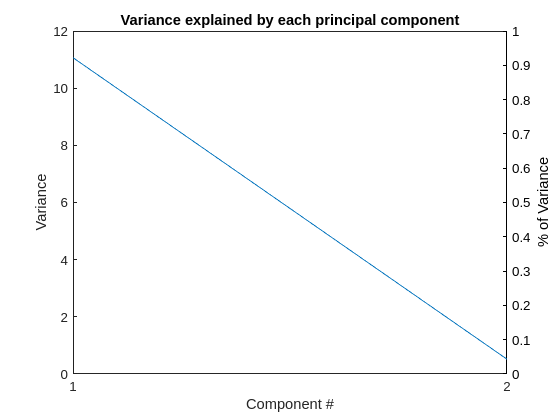

plot_var(A)

eta = diag(A / trace(A));
eta

eta =     0.9554
    0.0446


## PROBLEM 5

Using the data from Problem 4:

**a) Calculate a 95% confidence ellipse for the mean of the population.**

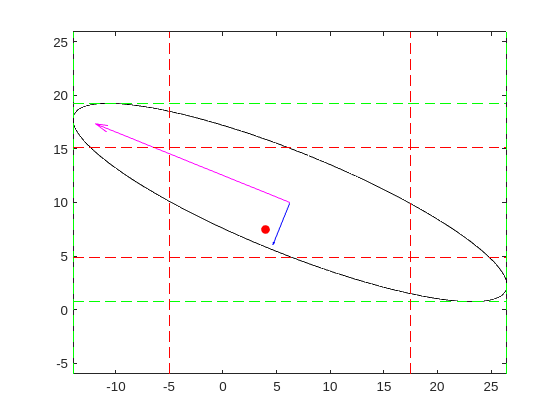

alpha = 0.05;
drawCI(X, alpha)
hold on;
scatter(4, 7.5, 'or', 'filled');

**b) Use the confidence ellipse to decide whether H0 : μ = [4, 7.5]T can be rejected at α = 0.05 significance level.**

Cannot be rejected.

**c) Calculate individual 95% confidence intervals of the mean for each dimension of X (Hint: use Bonferroni correction). Do your reach the same conclusion as (b) using these intervals?**

Same conclusion from the plot.

**d) Calculate individual 95% confidence intervals of the mean for each principal component. Do your reach the same conclusion as (b) using these intervals?**

## PROBLEM 6

When decomposing the sample covariance matrix from a certain dataset X consisting of a total of 6 samples, we obtain the following eigenvalues and eigenvector matrices (Λ and P, respectively):

ord_eval = [9.8892 0 0; 0 4.8579 0; 0 0 0.4530];
ord_evec = [-0.3874 -0.5496 0.7401; 0.8941 -0.0283 0.4470; -0.2247 0.8349 0.5024];

We are also given the coordinates of our 6 samples in PCA space (i.e. the projections of the original samples in the direction of the eigenvectors indicated above):

Y = [
        2.0129 -4.1265 0.9561 1.6069 3.2944 -3.7438;
        -0.8916 -1.8209 -2.2478 3.2904 -0.3703 2.0401;
        0.3915 -0.8100 0.1823 -0.7686 0.0983 0.9065
    ];

**a) Can you reconstruct the coordinates of the samples X (in the original space)? (Yes / No - Justify).**

No. We lack information about the center of the data. If we assume that it is zero we can proceed.

**b) If you answer YES to (a), reconstruct the samples. If you answer NO, then indicate what else you need to assume to be able to reconstruct the original samples. Make a reasonable assumption and proceed to the calculation.**

center = zeros(3, 1);
data = reconstruct(Y, ord_evec, center);
data

data =    -0.0000    1.9999    0.9999   -2.9998   -1.0000    1.0000
    2.0000   -4.0000    0.9999    1.0000    2.9999   -2.9999
   -1.0000   -1.0000   -1.9999    1.9999   -1.0000    2.9999


**c) What percentage of variance from the original data can you explain if you retain only the first 2 principal components?**

k = 2;
eta = proportion_of_var(ord_eval, k);
eta

eta = 0.9702

**d) Reconstruct the original sample coordinates as done in (b), but using only the first 2 principal components.**

evec_hat = ord_evec(:, 1:k);
Y_hat = Y(1:k, :);
data_hat = reconstruct(Y_hat, evec_hat, center);
data_hat

data_hat =    -0.2898    2.5994    0.8650   -2.4309   -1.0727    0.3291
    1.8250   -3.6380    0.9185    1.3436    2.9560   -3.4051
   -1.1967   -0.5930   -2.0915    2.3861   -1.0494    2.5445


**e) Quantify how much is the difference between your results in (d) with respect to those in (b).**

re = relative_error(data, data_hat);
re

re = 0.0298

**f) How do your answers to (e) and (c) relate to each other?**

The relative error is the proportion of the variance that is not explained by the first k selected principal components (i.e.: $\textrm{Relative}\;\textrm{Error}=1-\eta$).

## PROBLEM 7

Table 1 shows the approximate straight-line distances between a few Spanish cities.

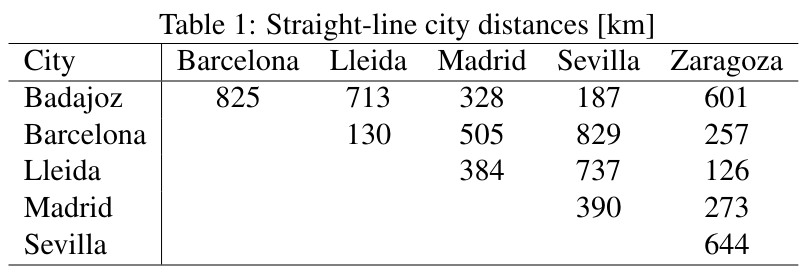

**a) Re-arrange the information from the table in the form of a 6 × 6 matrix of pair-wise distances.**

labels = ["Badajoz" "Barcelona" "Lleida" "Madrid" "Sevilla" "Zaragoza"];
D = [
    0  825 713 328 187 601;
    0   0  130 505 829 257;
    0   0   0  384 737 126;
    0   0   0   0  390 273;
    0   0   0   0   0  644;
    0   0   0   0   0   0 ;
    ];
D = D + D'

D =      0   825   713   328   187   601
   825     0   130   505   829   257
   713   130     0   384   737   126
   328   505   384     0   390   273
   187   829   737   390     0   644
   601   257   126   273   644     0


**b) Convert the matrix obtained in (a) to the matrix of inner products B, i.e. one with entries **$\textbf{\{}\mathbf{b_{ij}=x_i^T \cdot x_j}\textbf{\}}$.

% B = HAH' where A = (...)D and H is diagonal of ones - matrix of ones * (...)
n = size(D, 1);
H = eye(n) - ones(n)/n;
A = - (D .^2) / 2;
B = H * A * H'

B = 1.0e+05 *

    1.6918   -1.7004   -1.2341    0.3572    1.6332   -0.7478
   -1.7004    1.7137    1.2341   -0.3691   -1.6172    0.7389
   -1.2341    1.2341    0.9236   -0.2263   -1.2919    0.5947
    0.3572   -0.3691   -0.2263    0.0984    0.2509   -0.1111
    1.6332   -1.6172   -1.2919    0.2509    1.9243   -0.8992
   -0.7478    0.7389    0.5947   -0.1111   -0.8992    0.4246


**c) Perform eigendecomposition of matrix B and determine the number of dimensions to retain.**

Intuitively this is a map so ideally we should have two dimensions.

[evec, eval] = eig(B);
[~, idxs] = sort(diag(eval), 'descend');
idxs = idxs(diag(eval(idxs, idxs)) >= 0); % remove also negative components
ord_eval = eval(idxs, idxs)

ord_eval = 1.0e+05 *

    6.4441         0         0         0
         0    0.3354         0         0
         0         0    0.0058         0
         0         0         0    0.0020


ord_evec = evec(:, idxs)

ord_evec =    -0.5056   -0.3621    0.1501   -0.6187
    0.5059    0.4417    0.1370   -0.4864
    0.3793   -0.0294   -0.4772    0.0822
   -0.0964   -0.3489   -0.5292    0.2236
   -0.5258    0.6526    0.0495    0.3518
    0.2427   -0.3540    0.6697    0.4474


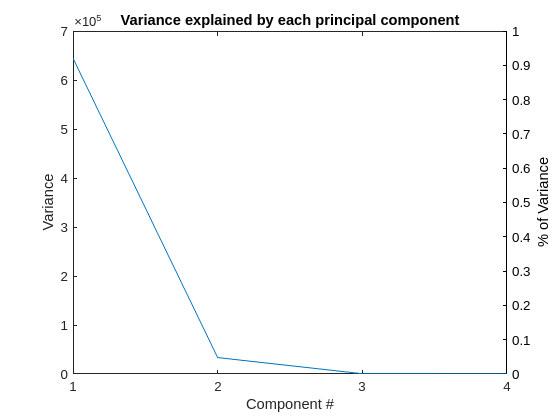

plot_var(ord_eval)

It makes sense to keep the first two based on the elbow method.

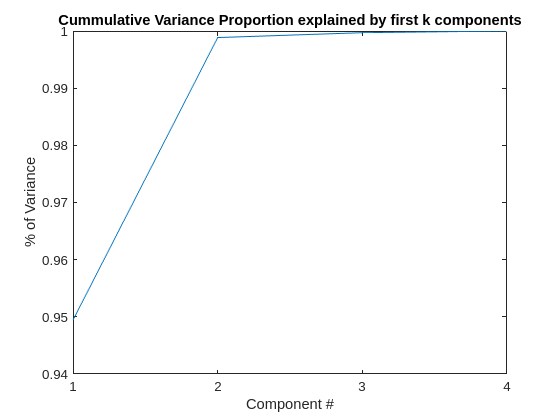

eval_count = size(ord_eval, 1);
eta = zeros(eval_count, 1);
for i=1:eval_count
    eta(i) = proportion_of_var(ord_eval, i);
end

figure;
plot(eta);
title('Cummulative Variance Proportion explained by first k components');
xlabel('Component #');
xticks(1:eval_count);
ylabel('% of Variance');

In general it seems reasonable to keep the first two principal components.

**d) Obtain the configuration of the cities listed in the table in the embedding space.**

evec_hat = ord_evec(:, 1:k);
center = zeros(n, 1);

% RESPUESTA DE FEDE: SE HACE CON EIGVAL^1/2*EIGVEC' NO CON B NI D PORQUE YA
% TENEMOS LA EIGDECOMPOSITION HECHO
embedding = sqrt(ord_eval(1:k, 1:k))*evec_hat';
% embedding = embed(D, evec_hat, center); % HERE USE D OR B ???
embedding = embedding([2, 1], :) % axes are mirrored

embedding =   -66.3133   80.8895   -5.3782  -63.8872  119.5178  -64.8287
 -405.8853  406.0837  304.4461  -77.4208 -422.0474  194.8237


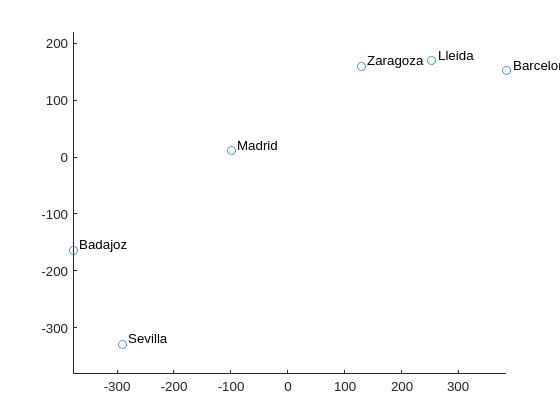

angle = -1;
rotation_matrix = [cos(angle) -sin(angle); sin(angle) cos(angle)];
rotated_embedding = rotation_matrix * embedding;

figure;
scatter(rotated_embedding(1,:), rotated_embedding(2,:))
% inspo from https://es.mathworks.com/matlabcentral/answers/97277-how-can-i-apply-data-labels-to-each-point-in-a-scatter-plot-in-matlab-7-0-4-r14sp2#answer_106626
dx = 10; dy = 10; % displacement so the text does not overlay the data points
text(rotated_embedding(1,:)+dx, rotated_embedding(2,:)+dy, labels);
axis('equal');

Looks slightly accurate.

**e) Compute the distances between all pairs of cities in the embedding space. Compare the results to those indicated in the table (hint: make a scatter plot between them).**

D_hat = zeros(n);
for i=1:n
    for j=i+1:n
        D_hat(i, j) = euclidean_dist(embedding(:, i), embedding(:, j));
    end
end
D_hat = D_hat + D_hat'

D_hat =          0  825.2044  712.9403  328.4734  186.5326  600.7109
  825.2044         0  133.3128  504.7147  829.0315  256.6409
  712.9403  133.3128         0  386.3233  737.1511  124.7054
  328.4734  504.7147  386.3233         0  390.3907  272.2462
  186.5326  829.0315  737.1511  390.3907         0  643.8273
  600.7109  256.6409  124.7054  272.2462  643.8273         0


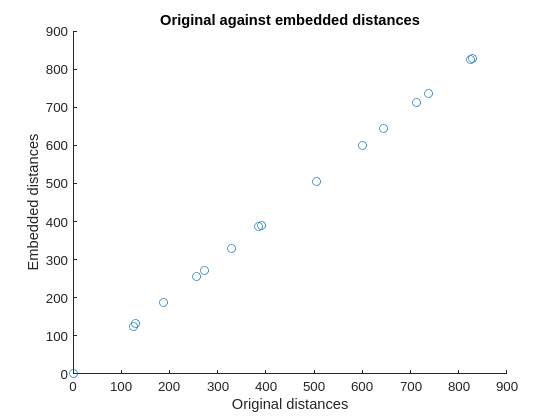

figure;
scatter(reshape(D, [], 1), reshape(D_hat, [], 1));
title('Original against embedded distances');
xlabel('Original distances');
ylabel('Embedded distances');

re = relative_error(D_hat, D);
re

re = 4.8197e-06

R = 1 - re

R = 1.0000